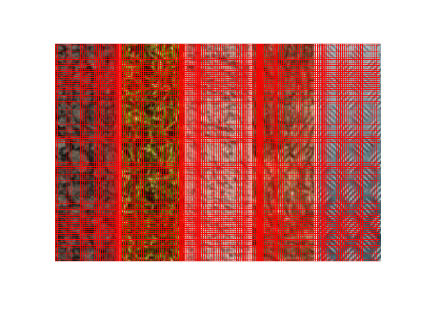

clear
close

small = imread('metall.jpg'); 
big = imread('textures.jpg');

% %apliquem filtre gausia per homogeneitzar aver si cuela xd
% small = imgaussfilt(small,2);
% big = imgaussfilt(big,2);

% Extraer características de textura de la imagen pequeña
small_features = extract_textural_features(small);

% Configurar parámetros de la ventana deslizante
window_size = size(small);
step_size = 5; % Tamaño del paso de la ventana deslizante

% Inicializar una matriz para almacenar las coordenadas de las regiones detectadas
detected_regions = [];

% Recorrer la imagen grande con la ventana deslizante
for i = 1:step_size:size(big, 1) - window_size(1) + 1
    for j = 1:step_size:size(big, 2) - window_size(2) + 1
        % Extraer una región de la imagen grande
        region = big(i:i+window_size(1)-1, j:j+window_size(2)-1);
        
        % Calcular características de textura de la región
        region_features = extract_textural_features(region);
        
        % Calcular la distancia entre las características de la región y las características de la imagen pequeña
        distancia = dist(region_features, small_features);
        
        % Si la distancia es menor que un cierto umbral, considerar la región como similar
        if distancia < 0.5%umbral
            % Almacenar las coordenadas de la región detectada
            detected_regions = [detected_regions; i, j];
        end
    end
end

% Marcar o identificar las regiones detectadas en la imagen grande
marked_image = insertShape(big, 'Rectangle', [detected_regions(:,2), detected_regions(:,1), window_size(2)*ones(size(detected_regions,1),1), window_size(1)*ones(size(detected_regions,1),1)], 'Color', 'red');
imshow(marked_image);